# 1. Import the data


clear;
clc;


% Define file IDs 
file_urls = {
    'normal_1', '1vp6kQ4FgtZ26NnHSCu7ZT_DJzikFK6D1';
    'normal_2', '12tRc-RxkcW-gYf5sfgxSLpFkozalT30f';
    'normal_3', '1IqBkXzdZpMwWTw6jBxia_GIRqeRm_XKn';
    'normal_4', '1UjFoQWdu5RlU6-JQbdjGrgfMjQ5ZOZ2G';
    'normal_5', '1ZEQQToBxm5x8lVpu9G_1Tht5ninVlLmc';
    'normal_6', '1XjRnKX0f0NtGBmCUbfvWYpKI7VZCQXmv';
    'viral_1', '1zXgvcuv10Zej13F9N2CtNROMR8w1l37t';
    'viral_2', '1ccZIUBOsHVKjDtR70H8gV3ikRGr86E1W';
    'viral_3', '1q5jLLbDVIp_tzp5V-y8cbHucemlYgA0s';
};

% Download and unzip the images

% Starting the loop
for i = 1:size(file_urls, 1)
    name = file_urls{i, 1};
    ID = file_urls{i, 2};
    
    % Construct download URL
    downloadURL = ['https://drive.google.com/uc?export=download&id=', ID];
    
    % Download the image file from the URL and save it locally
    websave([name, '.zip'], downloadURL);
    
    % Unzip the imported images
    unzip([name, '.zip'], name);
   
end
disp('Downloaded and extracted all images Sucessfully');

Downloaded and extracted all images Sucessfully



% Assign all the images in two cell arrays, one per class

% Define the folder paths for each class
normalFolderPaths = {'normal_1/normal_1','normal_2/normal_2','normal_3/normal_3', 'normal_4/normal_4', 'normal_5/normal_5','normal_6/normal_6'};
viralFolderPaths = {'viral_1/viral_1','viral_2/viral_2', 'viral_3/viral_3'};

% Initialize cell arrays to store the images for each class
normalImages = {};
viralImages = {};

% Process normal images
for j = 1:numel(normalFolderPaths)

    % Get a list of all files in the folder
    files = dir(fullfile(normalFolderPaths{j}, '*.jpeg'));
    
    % Iterate over each image file
    for i = 1:numel(files)

        % Read the image using imread
        imagePath = fullfile(normalFolderPaths{j}, files(i).name);
        normalImages{end+1} = imread(imagePath);
    end
end

% Process viral images
for j = 1:numel(viralFolderPaths)

    % Get a list of all files in the folder
    files = dir(fullfile(viralFolderPaths{j}, '*.jpeg'));
    
    % Iterate over each image file
    for i = 1:numel(files)

        % Read the image using imread
        imagePath = fullfile(viralFolderPaths{j}, files(i).name);
        viralImages{end+1} = imread(imagePath);
    end
end

## 2. Data Exploration


% Checking the number of images in each class
disp('Number of images in the viral class:')

Number of images in the viral class:


disp(length(viralImages))

   387



disp('Number of images in the normal class:')

Number of images in the normal class:


disp(length(normalImages))

   387



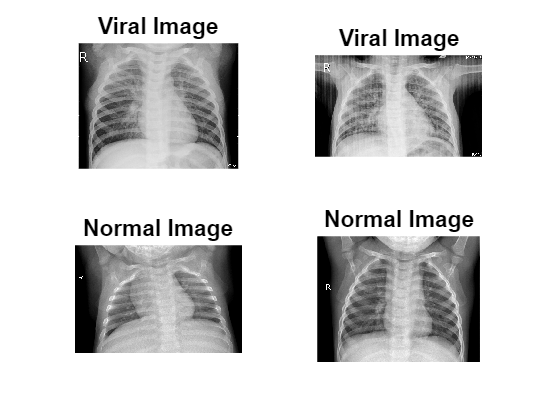



% Display some actual random xray images to see what the images looks like

% Define the number of images to display from each class
num_images_per_class = 2;

% Display random selection of images from viral class
figure;
for i = 1:num_images_per_class
    subplot(2, num_images_per_class, i);
    imshow(viralImages{randi(numel(viralImages))});
    title('Viral Image');
end

% Display random selection of images from normal class
for i = 1:num_images_per_class
    subplot(2, num_images_per_class, num_images_per_class + i);
    imshow(normalImages{randi(numel(normalImages))});
    title('Normal Image');
    
end

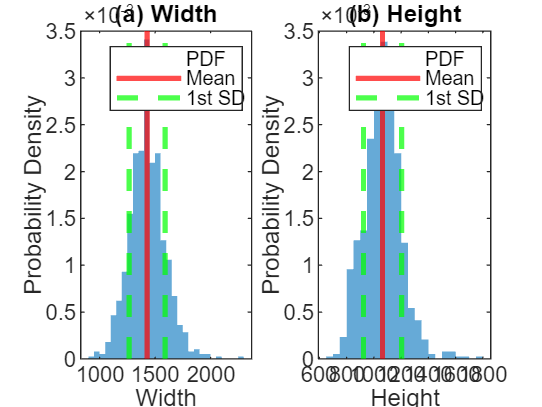


% Investigating Height and widths of the images

% First get the height and width of images

% Initialize arrays to store width and height of each image
widths = zeros(1, numel(normalImages) + numel(viralImages));
heights = zeros(1, numel(normalImages) + numel(viralImages));

% Iterate through normal images
for i = 1:numel(normalImages)
    [height, width, ~] = size(normalImages{i});
    widths(i) = width;
    heights(i) = height;
end

% Iterate through viral images
for i = 1:numel(viralImages)
    [height, width, ~] = size(viralImages{i});
    widths(numel(normalImages) + i) = width;
    heights(numel(normalImages) + i) = height;
end

% Plotting histograms for width and height
figure;

% Histogram for width
subplot(1, 2, 1);
histogram(widths, 'Normalization', 'pdf', 'EdgeColor', 'none');
xlabel('Width');
ylabel('Probability Density');
title('(a) Width');

% Calculate mean and standard deviation for width
mean_width = mean(widths);
std_width = std(widths);

% Plot mean and first standard deviation for width
hold on;
xline(mean_width, 'r', 'LineWidth', 2);
xline(mean_width + std_width, 'g--', 'LineWidth', 2);
xline(mean_width - std_width, 'g--', 'LineWidth', 2);
legend('PDF', 'Mean', '1st SD');
hold off;

% Histogram for height
subplot(1, 2, 2);
histogram(heights, 'Normalization', 'pdf', 'EdgeColor', 'none');
xlabel('Height');
ylabel('Probability Density');
title('(b) Height');

% Calculate mean and standard deviation for height
mean_height = mean(heights);
std_height = std(heights);

% Plot mean and first standard deviation for height
hold on;
xline(mean_height, 'r', 'LineWidth', 2);
xline(mean_height + std_height, 'g--', 'LineWidth', 2);
xline(mean_height - std_height, 'g--', 'LineWidth', 2);
legend('PDF', 'Mean', '1st SD');
hold off;



% Display the mean and standard deviation for width and height
disp('Width:');

Width:


fprintf('Mean: %.2f\n', mean_width);

Mean: 1428.37


fprintf('Standard Deviation: %.2f\n\n', std_width);

Standard Deviation: 161.71




disp('Height:');

Height:


fprintf('Mean: %.2f\n', mean_height);

Mean: 1063.46


fprintf('Standard Deviation: %.2f\n', std_height);

Standard Deviation: 139.78



% Counting the number of grayscale and color images 

% Initialize variables to count grayscale and color images
num_grayscale = 0;
num_color = 0;

% Concatenate viralImages and normalImages arrays into one
all_images = [viralImages normalImages];

% Iterate through all images
for i = 1:numel(all_images)
    % Check the dimension of the image matrix
    if ndims(all_images{i}) == 2
        num_grayscale = num_grayscale + 1;
    elseif ndims(all_images{i}) == 3
        num_color = num_color + 1;
    end
end

% Display the results
fprintf('Number of grayscale images: %d\n', num_grayscale);

Number of grayscale images: 774


fprintf('Number of color images: %d\n', num_color);

Number of color images: 0


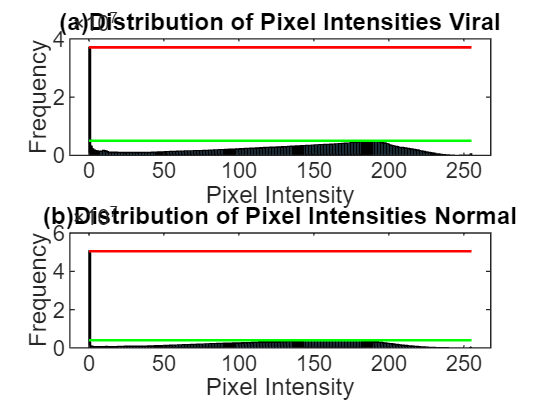



% Investigating pixel intsnsity distribution

% Initialize arrays to store pixel intensities
viral_pixel_intensities = [];
normal_pixel_intensities = [];

% Iterate through the viral images
for i = 1:numel(viralImages)
   
    % Flatten the image matrix to a vector and append to viral pixel intensities
    viral_pixel_intensities = [viral_pixel_intensities; viralImages{i}(:)];
end

% Iterate through the normal images
for i = 1:numel(normalImages)
   
    % Flatten the image matrix to a vector and append to normal pixel intensities
    normal_pixel_intensities = [normal_pixel_intensities; normalImages{i}(:)];
end


% Plot histograms of pixel intensities for viral and normal images
figure;

% Define the number of bins for the histogram
num_bins = 256; % 256 bins for grayscale images

% Create subplot
subplot(2,1,1);

% Compute histogram counts and bin edges
[viral_counts, viral_bins] = histcounts(viral_pixel_intensities, num_bins);
histogram(viral_pixel_intensities, viral_bins);% Plot the histogram

% Label x and y axis
xlabel('Pixel Intensity');  %
ylabel('Frequency');

% Set the title
title('(a)Distribution of Pixel Intensities Viral');

% Hold current plot for further plotting
hold on;

% Add line indicating maximum frequency
line([viral_bins(1), viral_bins(end)], [max(viral_counts), max(viral_counts)], 'Color', 'r', 'LineWidth', 1);

% Find second maximum frequency
sorted_viral_counts = sort(viral_counts, 'descend');
second_maxima = sorted_viral_counts(2);

% Add line on that second frequency
line([viral_bins(1), viral_bins(end)], [second_maxima, second_maxima], 'Color', 'g', 'LineWidth', 1);

% Find pixel intensity values of first and second highest frequency
first_maxima_viral = viral_bins(find(viral_counts == sorted_viral_counts(1), 1));
second_maxima_viral = viral_bins(find(viral_counts == sorted_viral_counts(2), 1));

% Similarly, plot for the 'normal' class, add lines and find out the values
% of first and second highest frequency
subplot(2,1,2);
[normal_counts, normal_bins] = histcounts(normal_pixel_intensities, num_bins);
histogram(normal_pixel_intensities, normal_bins);
xlabel('Pixel Intensity');
ylabel('Frequency');
title('(b)Distribution of Pixel Intensities Normal');
hold on;
line([normal_bins(1), normal_bins(end)], [max(normal_counts), max(normal_counts)], 'Color', 'r', 'LineWidth', 1);
sorted_normal_counts = sort(normal_counts, 'descend');
second_maxima = sorted_normal_counts(2);
line([normal_bins(1), normal_bins(end)], [second_maxima, second_maxima], 'Color', 'g', 'LineWidth', 1);

sorted_normal_counts = sort(normal_counts, 'descend');
first_maxima_normal = normal_bins(find(normal_counts == sorted_normal_counts(1), 1));
second_maxima_normal = normal_bins(find(normal_counts == sorted_normal_counts(2), 1));



% Print the first and second modes for viral images
fprintf('First Mode (Viral Images): %d, Frequency: %d\n', first_maxima_viral, max(viral_counts));

First Mode (Viral Images): 0, Frequency: 37070033


fprintf('Second Mode (Viral Images): %d, Frequency: %d\n', second_maxima_viral, sorted_viral_counts(2));

Second Mode (Viral Images): 1.874360e+02, Frequency: 4988403



% Print the first and second modes for normal images
fprintf('First Mode (Normal Images): %d, Frequency: %d\n', first_maxima_normal, max(normal_counts));

First Mode (Normal Images): 0, Frequency: 50481285


fprintf('Second Mode (Normal Images): %d, Frequency: %d\n', second_maxima_normal, sorted_normal_counts(2));

Second Mode (Normal Images): 1.655020e+02, Frequency: 3991515


## 3. Image preprocessing


% Resize the image for consitency

% Define the target size
target_size = [224, 224];

% Initialize cell arrays to store resized images
resized_viralImages = cell(size(viralImages));
resized_normalImages = cell(size(normalImages));

% Resize viral images
for i = 1:numel(viralImages)
    resized_viralImages{i} = imresize(viralImages{i}, target_size);
end

% Resize normal images
for i = 1:numel(normalImages)
    resized_normalImages{i} = imresize(normalImages{i}, target_size);
end

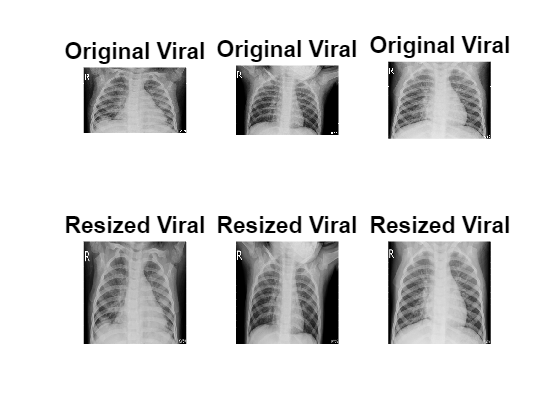



% Plot the original and resized images for viral images
figure;

% Plot original viral images
for i = 1:3
    subplot(2, 3, i);
    imshow(viralImages{i});
    title('Original Viral');
end

% Plot resized viral images
for i = 1:3
    subplot(2, 3, i+3);
    imshow(resized_viralImages{i});
    title('Resized Viral');
end

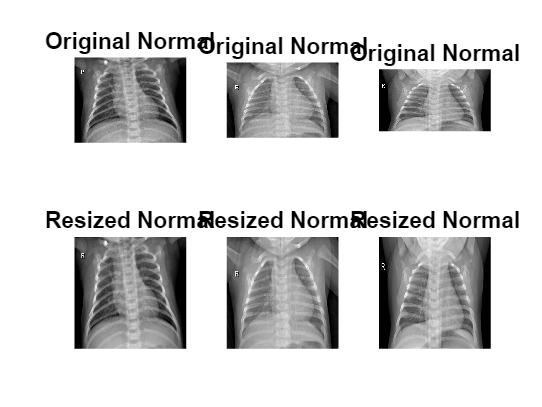


% Plot the original and resized images for normal images
figure;

% Plot original normal images
for i = 1:3
    subplot(2, 3, i);
    imshow(normalImages{i});
    title('Original Normal');
end

% Plot resized normal images
for i = 1:3
    subplot(2, 3, i+3);
    imshow(resized_normalImages{i});
    title('Resized Normal');
end


% Normalize the image between 0 and 1

% Normalize pixel values for viral images
for i = 1:numel(resized_viralImages)

    % Convert pixel values to double
    viralImages{i} = double(resized_viralImages{i});
    
    % Normalize pixel values to [0, 1]
    viralImages{i} = viralImages{i} / 255;
end

% Normalize pixel values for normal images
for i = 1:numel(resized_normalImages)

    normalImages{i} = double(resized_normalImages{i});
    
    normalImages{i} = normalImages{i} / 255;
end


% Image concatination and labelling

% The normal images are labelled as 0 and viral are labelled as 1

% Determine the total number images on both calss
totalNormal = numel(normalImages);
totalViral = numel(viralImages);

% Concatenate the images from viram and normal
allImages = [normalImages(:); viralImages(:)];

% Create labels for the concatinated images
labels = [zeros(totalNormal, 1); ones(totalViral, 1)];


## 4. Initial training and evaluating models


% Convert images to a matrix suitable for feeding to a ML model

% Get the total number of images
numImages = numel(allImages);

% Get the size of the first image (all the image are resized in same height and width)
imageSize = size(allImages{1});

% Initialize a matrix to store the flattened images
imageMatrix = zeros(numImages, numel(allImages{1}));

% Reshape each image
for i = 1:numImages
    imageMatrix(i, :) = reshape(allImages{i}, 1, []);
end


% Training and testing split

%% Set random number generator seed for reproducibility
rng(42);

% Create a holdout cross-validation partition
cv = cvpartition(numImages, 'HoldOut', 0.25); % 25% of data for testing, 75% for training

% Obtain indices for training and testing data
trainIdx = cv.training(1); % Indices for training data
testIdx = cv.test(1); % Indices for testing data

% Split the data into training and testing sets based on the indices
trainImages = imageMatrix(trainIdx); % Training images
trainLabels = labels(trainIdx); % Training labels
testImages = imageMatrix(testIdx); % Testing images
testLabels = labels(testIdx); % Testing labels

% Display the number of images in the training and testing sets
fprintf('Number of training Images: %.2f\n', length(trainLabels))

Number of training Images: 581.00


fprintf('Number of testing Images: %.2f\n', length(testLabels))

Number of testing Images: 193.00



% Train SVM model

svmModel = fitcsvm(trainImages, trainLabels);

% Predict labels for test data

predictedLabels = predict(svmModel, testImages);

% Evaluate accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
disp(['Test Accuracy of SVM Model: ', num2str(accuracy * 100), '%']);

Test Accuracy of SVM Model: 46.114%



% Calculate confusion matrix
C = confusionmat(testLabels, predictedLabels);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 11


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 78


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 5


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 99


disp(['Precision: ', num2str(precision)]);

Precision: 0.6875


disp(['Recall: ', num2str(recall)]);

Recall: 0.1


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.1746


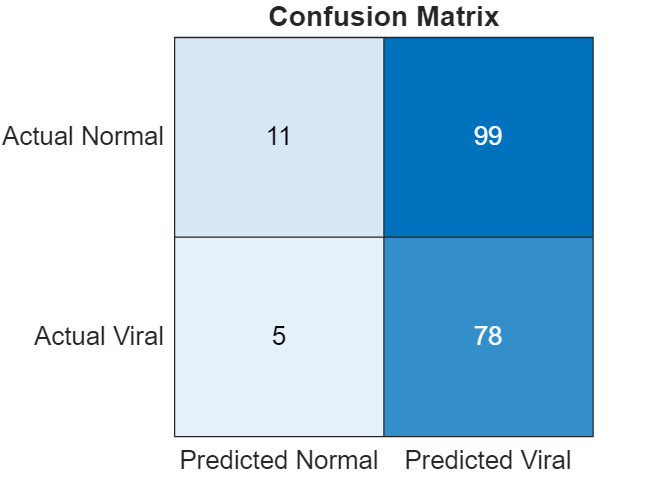


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');


% Train random forest classifier

% Define the number of trees for the random forest
numTrees = 100;

% Train the random forest classifier
rfModel = TreeBagger(numTrees, trainImages, trainLabels);

% Predict on the test data
testPredictions = str2double(predict(rfModel, testImages));

% Evaluate accuracy
testAccuracy = sum(testPredictions == testLabels) / numel(testLabels);
fprintf('Test Accuracy Random Forest Model: %.3f%%\n', testAccuracy * 100);

Test Accuracy Random Forest Model: 56.477%



% Calculate confusion matrix
C = confusionmat(testLabels, testPredictions);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 70


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 39


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 44


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 40


disp(['Precision: ', num2str(precision)]);

Precision: 0.61404


disp(['Recall: ', num2str(recall)]);

Recall: 0.63636


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.625


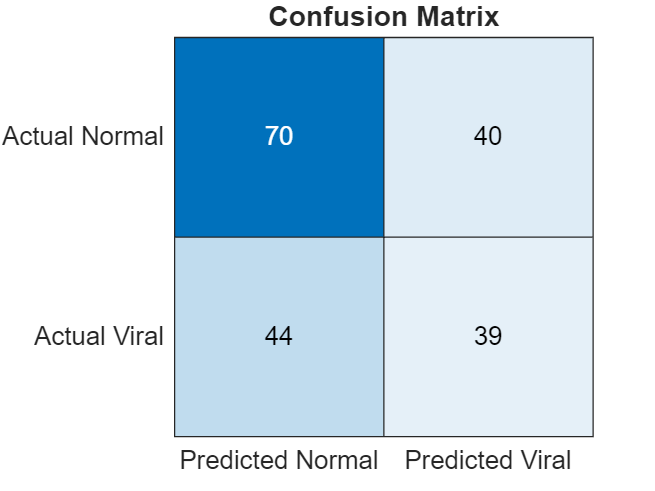


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');

## 5. Feature Engineering


% Extracting HOG Features

% Setting the cell size of HOG that runs across the image
cellSize = [8 8];

% Initialize an array to store the HOG features and corresponding labels
hogFeatures = [];
hog_labels = [];

% Iterate through each binary image
for i = 1:length(allImages)
    % Extract HOG features    
    hogFeature = extractHOGFeatures(allImages{i}, 'CellSize', cellSize);

    % Append HOG features to the matrix
    hogFeatures = [hogFeatures; hogFeature];

    % Assign a label
    hog_labels = [hog_labels; labels(i)];
end

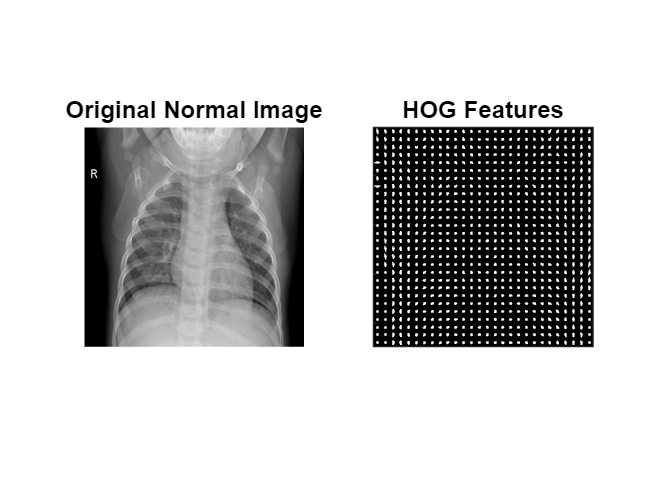


% Checking how the HOG Features looks like

% Generate two random indices
index1 = randi(length(resized_normalImages));
index2 = randi(length(resized_viralImages));

[hogFeature_1, visualization_1] = extractHOGFeatures(resized_normalImages{index1});
[hogFeature_2, visualization_2] = extractHOGFeatures(resized_viralImages{index2});

% Plot the first image
figure;
subplot(1, 2, 1);
imshow(resized_normalImages{index1});
title('Original Normal Image');

% Plot the HOG features for the first image
subplot(1, 2, 2);
plot(visualization_1);
title('HOG Features');

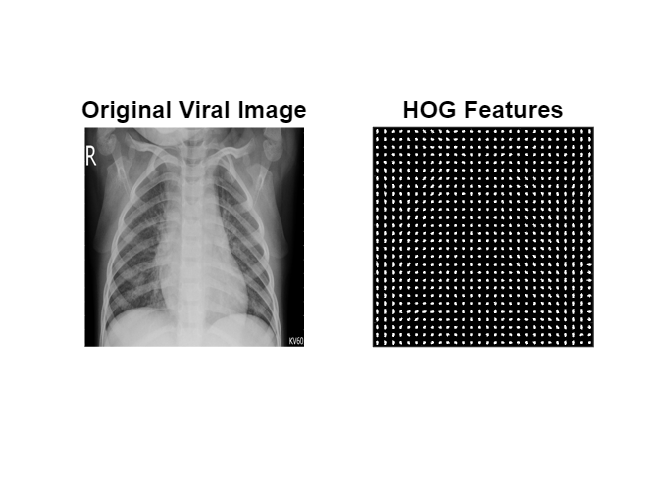



% Plot the second image
figure;
subplot(1, 2, 1);
imshow(resized_viralImages{index2});
title('Original Viral Image');

% Plot the HOG features for the second image
subplot(1, 2, 2);
plot(visualization_2);
title('HOG Features');

## 6. Training the model with HOG features and evaluating the performance


% Making the HOG features ready to feed the machine learning model

% Also ensuring that classes (viral and normal) are evenly distributed among train and test 

% Determine the number of samples
num_samples = size(hogFeatures, 1);

% Calculate the index for a 75/25 split
splitIndex = round(0.75 * num_samples);

% Shuffle the data
rand_indices = randperm(num_samples);
shuffledFeatures = hogFeatures(rand_indices, :);
shuffledLabels = hog_labels(rand_indices);

% Initialize variables to store train and test data
trainFeatures = [];
trainLabels = [];
testFeatures = [];
testLabels = [];

% Iterate through each class
for classLabel = [0, 1]
    % Find indices of current class
    classIndices = find(shuffledLabels == classLabel);
    
    % Calculate number of samples for current class
    num_class_samples = length(classIndices);
    
    % Calculate split index for current class
    splitIndex_class = round(0.75 * num_class_samples);
    
    % Split indices for current class
    trainIndices_class = classIndices(1:splitIndex_class);
    testIndices_class = classIndices(splitIndex_class+1:end);
    
    % Append features and labels for current class to train and test sets
    trainFeatures = [trainFeatures; shuffledFeatures(trainIndices_class, :)];
    trainLabels = [trainLabels; shuffledLabels(trainIndices_class)];
    testFeatures = [testFeatures; shuffledFeatures(testIndices_class, :)];
    testLabels = [testLabels; shuffledLabels(testIndices_class)];
end



% Check the number of testing and training images
fprintf('Number of training Images: %.2f\n', length(trainLabels))

Number of training Images: 580.00


fprintf('Number of testing Images: %.2f\n', length(testLabels))

Number of testing Images: 194.00



% Count the occurrences of 1s and 0s in trainLabels
train_label_ones_count = sum(trainLabels == 1);
train_label_zeros_count = sum(trainLabels == 0);

% Count the occurrences of 1s and 0s in testLabels
test_label_ones_count = sum(testLabels == 1);
test_label_zeros_count = sum(testLabels == 0);

% Display the counts
fprintf('Train images: Number of viral images = %d, Number of Normal Images = %d\n', train_label_ones_count, train_label_zeros_count);

Train images: Number of viral images = 290, Number of Normal Images = 290


fprintf('Test images: Number of viral Images = %d, Number of normal Images = %d\n', test_label_ones_count, test_label_zeros_count);

Test images: Number of viral Images = 97, Number of normal Images = 97



% Start timing
tic;

% Train the SVM classifier
SVMModel = fitcsvm(trainFeatures, trainLabels);

% Stop timing
training_time_svm = toc;

% Display the time taken to train the model
fprintf('Training time for SVM Model: %.2f seconds\n', training_time_svm);

Training time for SVM Model: 1.00 seconds



% Predict labels for the test data
svmpredictedLabels = predict(SVMModel, testFeatures);

% Evaluate the performance
accuracySVM = sum(svmpredictedLabels == testLabels) / length(testLabels);
fprintf('SVM Accuracy: %.2f%%\n', accuracySVM * 100);

SVM Accuracy: 94.33%



% Further evaluation

% Calculate confusion matrix
C = confusionmat(testLabels, svmpredictedLabels);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 94


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 89


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 8


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 3


disp(['Precision: ', num2str(precision)]);

Precision: 0.92157


disp(['Recall: ', num2str(recall)]);

Recall: 0.96907


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.94472


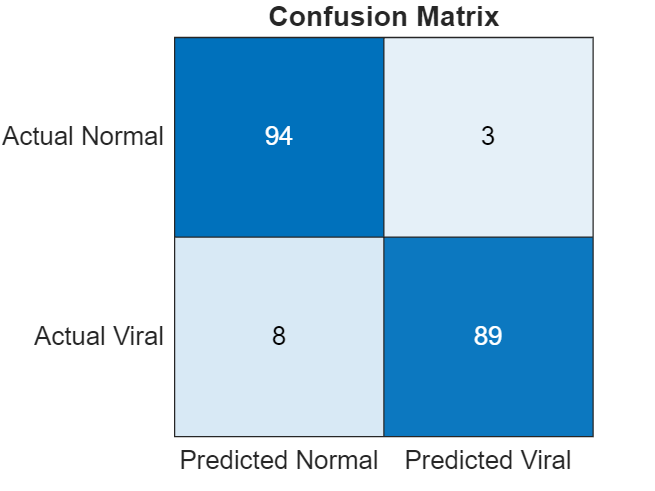


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');

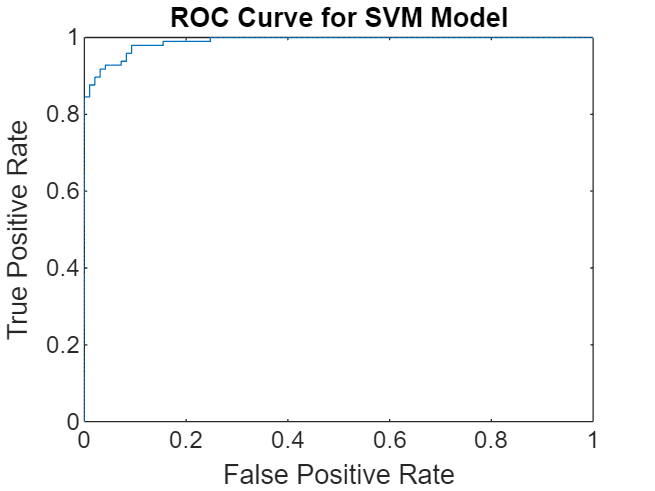


% Predict probabilities for each class
[~, SVMScores] = predict(SVMModel, testFeatures);

% Extract positive class scores
positiveClassScores = SVMScores(:, 2); % Assuming positive class is 1

% Calculate ROC curve and AUC
[X,Y,T,AUC] = perfcurve(testLabels, positiveClassScores, 1);

% Plot ROC curve
plot(X,Y);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve for SVM Model');


% Calculate AUC
disp(['AUC for SVM Model: ', num2str(AUC)]);

AUC for SVM Model: 0.98969



% Train the Random Forest model using TreeBagger

numTrees = 75; % Number of trees in the forest

% Start timing
tic;

RandomForestModel = TreeBagger(numTrees, trainFeatures, trainLabels, 'Method', 'classification');

% Stop timing
training_time_rf = toc;

% Display the time taken to train the model
fprintf('Training time for Random Forest Model: %.2f seconds\n', training_time_rf);

Training time for Random Forest Model: 4.84 seconds



% Predict labels for the test data
predictedLabelsRF = str2double(predict(RandomForestModel, testFeatures));

% Evaluate the performance
accuracyRF = sum(predictedLabelsRF == testLabels) / length(testLabels);
fprintf('Random Forest Accuracy: %.2f%%\n', accuracyRF * 100);

Random Forest Accuracy: 89.69%



% Further Evaluation

% Calculate confusion matrix
C = confusionmat(testLabels, predictedLabelsRF);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 87


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 87


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 10


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 10


disp(['Precision: ', num2str(precision)]);

Precision: 0.89691


disp(['Recall: ', num2str(recall)]);

Recall: 0.89691


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.89691


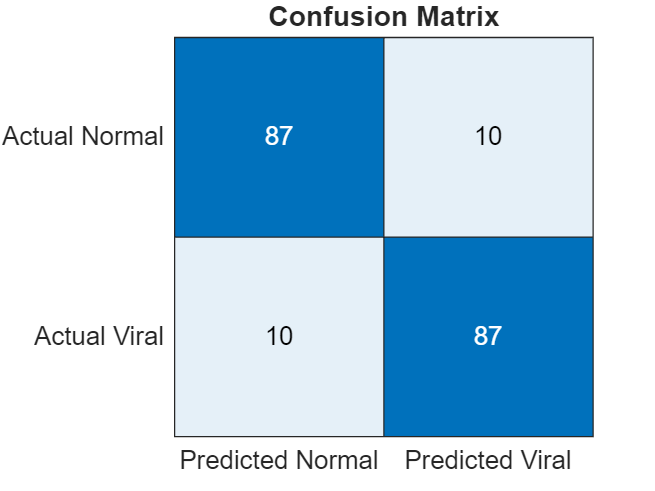


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');

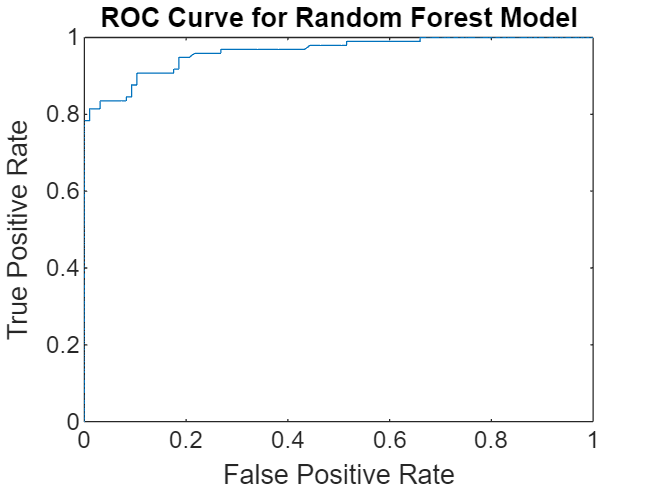


% Predict probabilities for each class
[~,scores] = predict(RandomForestModel, testFeatures);

% Extract positive class probabilities
positiveClassIndex = find(strcmp(RandomForestModel.ClassNames, '1')); % Find index of positive class label '1'
positiveClassProbabilitiesRF = scores(:, positiveClassIndex);

% Calculate ROC curve and AUC
[X,Y,T,AUC] = perfcurve(testLabels, positiveClassProbabilitiesRF, 1);

% Plot ROC curve
plot(X,Y);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve for Random Forest Model');


% Display AUC
disp(['AUC for Random Forest Model: ', num2str(AUC)]);

AUC for Random Forest Model: 0.96301


## 7. Further preprocessing the images


% Applying Anisotropic Diffusion filter

% Number of epochs
num_iter = 4;

% Time step
lambda = 0.12;

% Edge threshold
kappa = 75;

% Getting the rows and columns
[rows, cols] = size(allImages(1));

% Get the number of images
num_images = length(allImages);

% Initialize a cell array to store the filtered images
filteredImages = cell(1, num_images);

for i = 1:num_images

    % Extract the current  image
    image = allImages{i};

    % Initialize the filtered image
    ad_filteredImage = image;

    for t = 1:num_iter
        % Calculate gradients
        deltaN = ad_filteredImage([2:rows, rows], :) - ad_filteredImage;
        deltaS = ad_filteredImage - ad_filteredImage([1, 1:rows-1], :);
        deltaE = ad_filteredImage(:, [2:cols, cols]) - ad_filteredImage;
        deltaW = ad_filteredImage - ad_filteredImage(:, [1, 1:cols-1]);

        % Compute conduction coefficients
        cN = exp(-(deltaN/kappa).^2);
        cS = exp(-(deltaS/kappa).^2);
        cE = exp(-(deltaE/kappa).^2);
        cW = exp(-(deltaW/kappa).^2);

        % Update the image using the PDE formula
       ad_filteredImage = ad_filteredImage + lambda * (cN .* deltaN + cS .* deltaS + cE .* deltaE + cW .* deltaW);
    end

    % Store the filtered image in the output cell array
    ad_filteredImages{i} = ad_filteredImage;
end

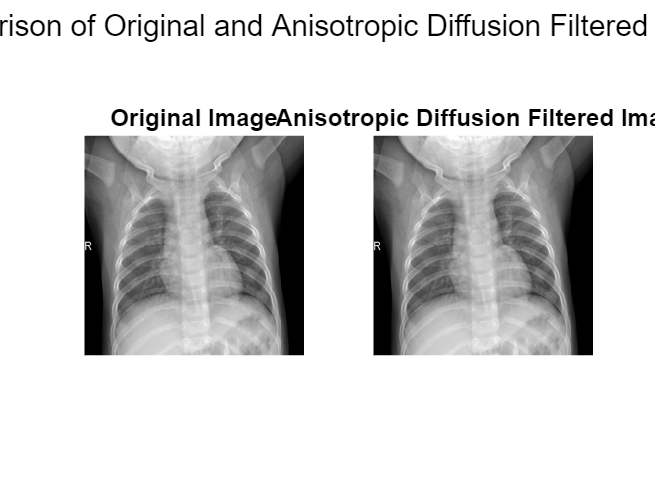


% Generate a random index
index = randi(num_images);

% Original image
originalImage = allImages{index};

% Anisotropic Diffusion filtered image
adf_filteredImage = ad_filteredImages{index};

% Plot the original image and the Anisotropic Diffusion filtered image side by side
figure;

% Plot the original image
subplot(1, 2, 1);
imshow(originalImage);
title('Original Image');

% Plot the Anisotropic Diffusion filtered image
subplot(1, 2, 2);
imshow(adf_filteredImage);
title('Anisotropic Diffusion Filtered Image');

% Adjust the figure to display properly
sgtitle('Comparison of Original and Anisotropic Diffusion Filtered Images');


% Performing the thresholding
% Define the normalized threshold values
lowerThreshold = 0.651;
upperThreshold = 0.733;

% Initialize a cell array to store the thresholded images
thresholdedImages = cell(size(ad_filteredImages));

% Iterate through each image in the cell array
for i = 1:length(ad_filteredImages)
    % Extract the current image
    image = ad_filteredImages{i};

    % Apply thresholding based on the specified intensity range
    thresholdedImage = image;
    thresholdedImage(image < lowerThreshold) = 0;  % Set pixels below lower threshold to 0 (pitch black)
    thresholdedImage(image > upperThreshold) = 0;  % Set pixels above upper threshold to 0 (pitch black)

    % Store the thresholded image in the output cell array
    thresholdedImages{i} = thresholdedImage;
end

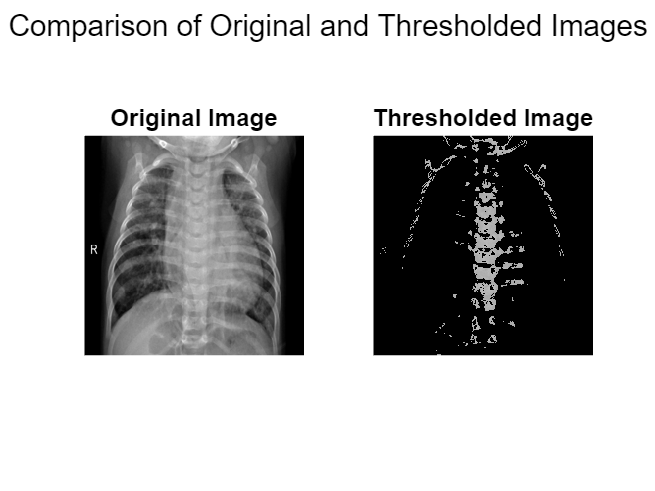


% Generate a random index
index = randi(num_images);

% Original image
originalImage = allImages{index};

% Thresholded image
thresholdedImage = thresholdedImages{index};

% Plot the original image and the thresholded image side by side
figure;

% Plot the original image
subplot(1, 2, 1);
imshow(originalImage);
title('Original Image');

% Plot the thresholded image
subplot(1, 2, 2);
imshow(thresholdedImage);
title('Thresholded Image');

% Adjust the figure to display properly
sgtitle('Comparison of Original and Thresholded Images');


% Extracting HOG Features

% Setting the cell size of HOG that runs across the image
cellSize = [8 8];

% Initialize an array to store the HOG features and corresponding labels
hogFeatures = [];
hog_labels = [];

% Iterate through each binary image
for i = 1:length(thresholdedImages)
    % Extract HOG features    
    hogFeature = extractHOGFeatures(thresholdedImages{i}, 'CellSize', cellSize);

    % Append HOG features to the matrix
    hogFeatures = [hogFeatures; hogFeature];

    % Assign a label
    hog_labels = [hog_labels; labels(i)];
end



% Making the HOG features ready to feed the machine learning model
% Also ensuring that classes (viral and normal) are evenly distributed among train and test 

% Determine the number of samples
num_samples = size(hogFeatures, 1);

% Calculate the index for a 75/25 split
splitIndex = round(0.75 * num_samples);

% Shuffle the data
rand_indices = randperm(num_samples);
shuffledFeatures = hogFeatures(rand_indices, :);
shuffledLabels = hog_labels(rand_indices);

% Initialize variables to store train and test data
trainFeatures = [];
trainLabels = [];
testFeatures = [];
testLabels = [];

% Iterate through each class
for classLabel = [0, 1]
    % Find indices of current class
    classIndices = find(shuffledLabels == classLabel);
    
    % Calculate number of samples for current class
    num_class_samples = length(classIndices);
    
    % Calculate split index for current class
    splitIndex_class = round(0.75 * num_class_samples);
    
    % Split indices for current class
    trainIndices_class = classIndices(1:splitIndex_class);
    testIndices_class = classIndices(splitIndex_class+1:end);
    
    % Append features and labels for current class to train and test sets
    trainFeatures = [trainFeatures; shuffledFeatures(trainIndices_class, :)];
    trainLabels = [trainLabels; shuffledLabels(trainIndices_class)];
    testFeatures = [testFeatures; shuffledFeatures(testIndices_class, :)];
    testLabels = [testLabels; shuffledLabels(testIndices_class)];
end



% Train test split
% Check the number of testing and training images
fprintf('Number of training Images: %.2f\n', length(trainLabels))

Number of training Images: 580.00


fprintf('Number of testing Images: %.2f\n', length(testLabels))

Number of testing Images: 194.00



% Count the occurrences of 1s and 0s in trainLabels
train_label_ones_count = sum(trainLabels == 1);
train_label_zeros_count = sum(trainLabels == 0);

% Count the occurrences of 1s and 0s in testLabels
test_label_ones_count = sum(testLabels == 1);
test_label_zeros_count = sum(testLabels == 0);

% Display the counts
fprintf('Train images: Number of viral images = %d, Number of Normal Images = %d\n', train_label_ones_count, train_label_zeros_count);

Train images: Number of viral images = 290, Number of Normal Images = 290


fprintf('Test images: Number of viral Images = %d, Number of normal Images = %d\n', test_label_ones_count, test_label_zeros_count);

Test images: Number of viral Images = 97, Number of normal Images = 97


## 8. Training and evaluating in the suspected threshold of viral infection



% Start timing
tic;

% Train the SVM classifier
SVMModelV2 = fitcsvm(trainFeatures, trainLabels);

% Stop timing
training_time_svm = toc;

% Display the time taken to train the model
fprintf('Training time for SVM: %.2f seconds\n', training_time_svm);

Training time for SVM: 0.47 seconds



% Predict labels for the test data
svmpredictedLabels = predict(SVMModelV2, testFeatures);

% Evaluate the performance
accuracySVM = sum(svmpredictedLabels == testLabels) / length(testLabels);
fprintf('SVM Accuracy: %.2f%%\n', accuracySVM * 100);

SVM Accuracy: 91.24%



% Further evaluation

% Calculate confusion matrix
C = confusionmat(testLabels, svmpredictedLabels);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 85


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 92


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 5


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 12


disp(['Precision: ', num2str(precision)]);

Precision: 0.94444


disp(['Recall: ', num2str(recall)]);

Recall: 0.87629


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.90909


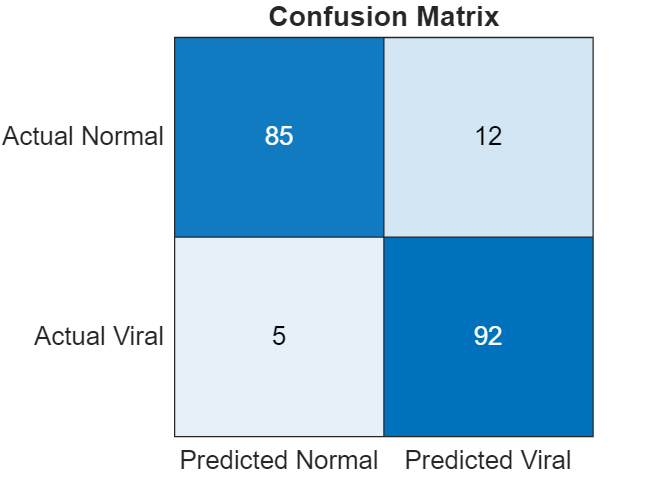


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');


% Train the Random Forest model using TreeBagger

% Start timing
tic;

numTrees = 65; % Number of trees in the forest
RandomForestModelV2 = TreeBagger(numTrees, trainFeatures, trainLabels, 'Method', 'classification');

% Stop timing
training_time_rf = toc;

% Display the time taken to train the model
fprintf('Training time for Random Forest: %.2f seconds\n', training_time_rf);

Training time for Random Forest: 4.20 seconds




% Predict labels for the test data
predictedLabelsRF = str2double(predict(RandomForestModelV2, testFeatures));

% Evaluate the performance
accuracyRF = sum(predictedLabelsRF == testLabels) / length(testLabels);
fprintf('Random Forest Accuracy: %.2f%%\n', accuracyRF * 100);

Random Forest Accuracy: 86.60%



% Further evaluation

% Calculate confusion matrix
C = confusionmat(testLabels, predictedLabelsRF);

% Calculate true positives (TP), false positives (FP), false negatives (FN)
TP = C(1, 1);
FP = C(2, 1);
FN = C(1, 2);
TN = C(2, 2);

% Calculate precision, recall, and F1 score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display TP, TN, FP, FN, precision, recall, and F1 score
disp(['True Positives (TP): ', num2str(TP)]);

True Positives (TP): 78


disp(['True Negatives (TN): ', num2str(TN)]);

True Negatives (TN): 90


disp(['False Positives (FP): ', num2str(FP)]);

False Positives (FP): 7


disp(['False Negatives (FN): ', num2str(FN)]);

False Negatives (FN): 19


disp(['Precision: ', num2str(precision)]);

Precision: 0.91765


disp(['Recall: ', num2str(recall)]);

Recall: 0.80412


disp(['F1 Score: ', num2str(f1_score)]);

F1 Score: 0.85714


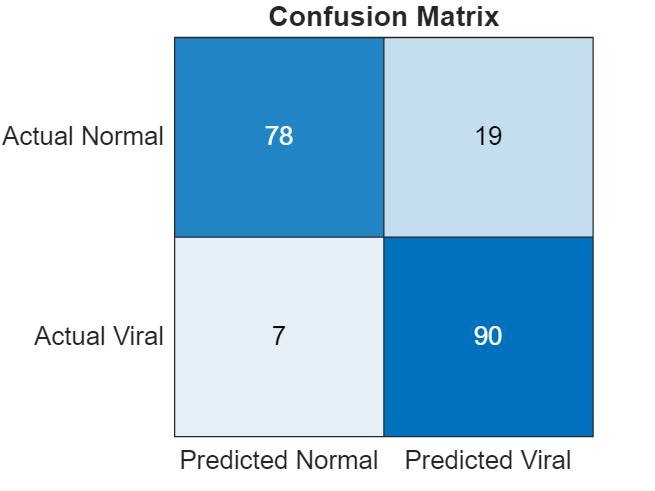


% Plot confusion matrix
figure;
heatmap({'Predicted Normal', 'Predicted Viral'}, {'Actual Normal', 'Actual Viral'}, C, 'ColorBarVisible', 'off', 'FontSize', 10);
title('Confusion Matrix');

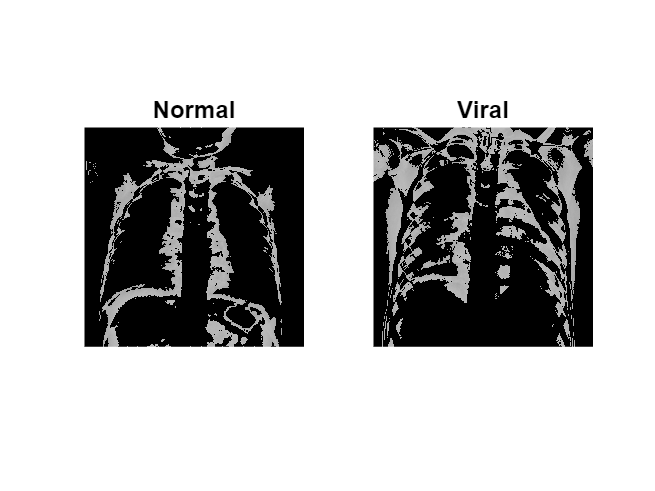


% Plot and check the thresholded images 
% Class 'normal'
indices_normal = find(labels == 0);  
index_normal = indices_normal(randi(length(indices_normal)));  
image_normal = thresholdedImages{index_normal};  

% Class 'viral'
indices_viral = find(labels == 1);  
index_viral = indices_viral(randi(length(indices_viral)));  
image_viral = thresholdedImages{index_viral};  

% Plot
figure;
subplot(1, 2, 1);
imshow(image_normal);
title('Normal');

subplot(1, 2, 2);
imshow(image_viral);
title('Viral');